# ESE 4481 - Final Project

David Young and Kenzie MacNicol

clear
clc
close all

% anonymous function to use in fsolve.
FunctoSolve = @(stVec) planeFunc(stVec(1), stVec(2), stVec(3), stVec(4), stVec(5), stVec(6), stVec(7), stVec(8), stVec(9), stVec(10), stVec(11), stVec(12));

% Tolerance for fsolve.
opt = optimoptions('fsolve', 'FunctionTolerance', 1e-6);
% Finding the numeric equilibrium points. Trim controls and states.
% We want the equilibrium to be where the drone is hovering 0.5meters off
% the ground.

%Trim States:
% State Vector. What I want the states to be:
% Pn = 0; % Want to hover at z = 0.5 meters.
% Pe = 0;
% Pd = -0.5;
% U = 0;
% v = 0; % no velocity in the east or down direction.
% w = 0;
% roll = 0;
% pitch = 0;
% yaw = 0;
% p = 0; % No atitude.
% q = 0;
% r = 0;


% Trim Controls: (NED configuration)
% fx = 0
% fy = 0
% fz = -mg


% Using fsolve to find the trim controls for hovering 0.5 meters off the
% ground.


% myGuess = [u; v; w; roll; pitch; yaw; p; q; r; l; m; n];
myGuess = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
[result, ~, exitFlg] = fsolve(FunctoSolve, myGuess, opt);


No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the function tolerance.

<stopping criteria details>



% Checks if all of the fsolve iterations produced a good result "fsolve completed because the vector of function values at the initial point
% is near zero as measured by the value of the function tolerance, and
% the problem appears regular as measured by the gradient."
if exitFlg>0
    fprintf('Converged!');
else
    fprintf('fsolve did not converge');
end

fsolve did not converge


%Display trim states and controls.
trimControl = result

trimControl =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Defining the system.
function f = planeFunc(u, v, w, phi, theta, psi, p, q, r, l, m, n) % Uknowns 
    
 
    mass = 0.033; % Units = kg. Mass of drone.
    radius = 0.046; % the individual motor arm length (from motor stator to the drone’s
                    % center of gravity).
    g = 9.8; % m/s^2.

    % Controller inputs: (fx, fy, fz, l, m, and n):

    % No force in x or y but just in the z direction.
    fx = 0;
    fy = 0;
    fz = -mass * g; % Hover.



    % constants of the system.
    % Atitude angles.
    
    cTheta = cosd(theta);
    cPhi = cosd(phi);
    cPsi = cosd(psi);
    
    sTheta = sind(theta);
    sPhi = sind(phi);
    sPsi = sind(psi);
    
    tTheta = tand(theta);
    
    
    
    %inerMatrix = Jy * eye(3); % Inertial Tensor matrix.
    inerMatrix = [16.57,  0.83,  0.72;
                   0.83, 16.66,  1.80;
                   0.72,  1.80, 29.26]; % Inertial Tensor matrix. In the body frame.
    
    Jx = inerMatrix(1, 1);
    Jxy = inerMatrix(2, 1);
    Jxz = inerMatrix(3, 1);
    %Jxy = inerMatrix(1, 2);
    Jy = inerMatrix(2, 2);
    Jyz = inerMatrix(3, 2);
    %Jxz = inerMatrix(1, 3);
    %Jyz = inerMatrix(2, 3);
    Jz = inerMatrix(3, 3);
    
    tau = Jx * Jz - Jxz^2;
    Tau1 = (Jxz * (Jx - Jy + Jz) ) / tau;
    Tau2 = (Jz * (Jz - Jy) + Jxz^2 ) / tau;
    Tau3 = Jz / tau;
    Tau4 = Jxz / tau;
    Tau5 = (Jz - Jx) / Jy;
    Tau6 = Jxz / Jy;
    Tau7 = ( (Jx - Jy) * Jx + Jxz^2) / tau;
    Tau8 = Jx / tau;
    % Creating the system of equations and putting it into a column vector.
    f = [(cTheta * cPsi) * u + (sPhi * sTheta * cPsi - cPhi * sPsi) * v + (cPhi * sTheta * cPsi + sPhi * sPsi)* w;
         (cTheta * sPsi) * u + (sPhi * sTheta * sPsi + cPhi * cPsi) * v + (cPhi * sTheta* sPsi - sPhi * cPsi) * w;
         (-sTheta) * u + (sPhi * cTheta) * v + (cPhi * cTheta) * w;
         r * v - q * w + fx / mass;
         p * w - r * u + fy / mass;
         q * u - p * v + fz / mass;
         p + (sPhi * tTheta) * q + (cPhi * tTheta) * r;
         0 + cPhi * q - sPhi * r;
         0 + (sPhi / cTheta) * q + (cPhi / cTheta) * r;
         (Tau1 * p * q - Tau2 * q * r) + Tau3 * l + Tau4 * n;
         Tau5 * p * r - Tau6 * (p^2 - r^2) + (1 / Jy) * m;
         Tau7 * p * q - Tau1 * q * r + Tau4 * l + Tau8 * n];


end                                                                                             



% Linearizing the system around the equilibrium.
% constants of the system.
clear
clc
close all

mass = 0.033; % Units = kg. Mass of drone.
radius = 0.046; % the individual motor arm length (from motor stator to the drone’s
                % center of gravity).
g = 9.8; % m/s^2.


syms u v w p q r fx fy fz l m n phi theta psi pn pe pd

% theta = 0;
% phi = 0;
% psi = 0;

cTheta = cosd(theta);
cPhi = cosd(phi);
cPsi = cosd(psi);

sTheta = sind(theta);
sPhi = sind(phi);
sPsi = sind(psi);

tTheta = tand(theta);


inerMatrix = [16.57,  0.83,  0.72;
               0.83, 16.66,  1.80;
               0.72,  1.80, 29.26]; % Inertial Tensor matrix. In the body frame.

Jx = inerMatrix(1, 1);
Jxy = inerMatrix(2, 1);
Jxz = inerMatrix(3, 1);
%Jxy = inerMatrix(1, 2);
Jy = inerMatrix(2, 2);
Jyz = inerMatrix(3, 2);
%Jxz = inerMatrix(1, 3);
%Jyz = inerMatrix(2, 3);
Jz = inerMatrix(3, 3);



tau = Jx * Jz - Jxz^2;
Tau1 = (Jxz * (Jx - Jy + Jz) ) / tau;
Tau2 = (Jz * (Jz - Jy) + Jxz^2 ) / tau;
Tau3 = Jz / tau;
Tau4 = Jxz / tau;
Tau5 = (Jz - Jx) / Jy;
Tau6 = Jxz / Jy;
Tau7 = ( (Jx - Jy) * Jx + Jxz^2) / tau;
Tau8 = Jx / tau;




f = [(cTheta * cPsi) * u + (sPhi * sTheta * cPsi - cPhi * sPsi) * v + (cPhi * sTheta * cPsi + sPhi * sPsi)* w;
     (cTheta * sPsi) * u + (sPhi * sTheta * sPsi + cPhi * cPsi) * v + (cPhi * sTheta* sPsi - sPhi * cPsi) * w;
     (-sTheta) * u + (sPhi * cTheta) * v + (cPhi * cTheta) * w;
     r * v - q * w + fx / mass;
     p * w - r * u + fy / mass;
     q * u - p * v + fz / mass;
     p + (sPhi * tTheta) * q + (cPhi * tTheta) * r;
     0 + cPhi * q - sPhi * r;
     0 + (sPhi / cTheta) * q + (cPhi / cTheta) * r;
     (Tau1 * p * q - Tau2 * q * r) + Tau3 * l + Tau4 * n;
     Tau5 * p * r - Tau6 * (p^2 - r^2) + (1 / Jy) * m;
     Tau7 * p * q - Tau1 * q * r + Tau4 * l + Tau8 * n];

% Computing jacobian.
A = jacobian(f, [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r]);
B = jacobian(f, [fx; fy; fz; l; m; n]);


% evaluating the jacobian at equilibrium points.
% pn, pe, pd, u, v, w, phi, theta, psi, p, q, r, fx, fy, fz, l, m, n.
equilPoint=[0; 0; -0.5; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; -m* g; 0; 0; 0];
aEval = double(subs(A, [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r; fx; fy; fz; l; m; n], equilPoint));
bEval = double(subs(B, [pn; pe; pd; u; v; w; phi; theta; psi; p; q; r; fx; fy; fz; l; m; n], equilPoint));


% Finding evalsof A to check stability of the system.
eVal = eig(aEval)

eVal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Controllability.
numStates = 12;
CMatrix = bEval;
for i = 1: numStates - 1
    CMatrix = [CMatrix, aEval^(i) * bEval]
end

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0
   30.3030         0         0         0         0         0         0         0         0         0         0         0
         0   30.3030         0         0         0         0         0         0         0         0         0         0
         0         0   30.3030         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.0604         0    0.0015
         0         0         0         0         0         0         0         0         0         0    0.0600         0
         0         0  

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0
   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   30.3030         0         0         0         0         0     

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   30.3030      

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   30.3030         0         0         0         0         0         0         0       

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   30.3030         0         0         0         0         0        

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0        

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

CMatrix =          0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0   30.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

rkCMat = rank(CMatrix);

% Testing for Full row rank.
if rkCMat == size(CMatrix, 1)
    disp('System is Controllable.')
else
    disp('NOT CONTROLLABLE!')
end

System is Controllable.


Creating the gains for the control inputs.



% creating the cascaded controller and the gains

% Controller for the thrust in the Z direction.
% Gain for the error between w and wCommanded
m = 0.033; % Mass of the drone.
Kw = 10 * (2 * pi) * m; % Want so that the corner frequency of the gain is 10 times less than 100 * (2 * pi).


% the closed loop transfer function of the inner most loop.
s = tf('s');
innerL = Kw / (m * s); % TF from W commanded to W.
innerTF = innerL / (1 + innerL);% Closed loop transfer function of the inner loop.
margin(innerL)

nyquist(innerL)
grid on


% The closed loop transfer function of the second loop.
Kpz = 2 * (2 * pi);% Want corner frequency at 5 times less than the corner freq of inner loop.
secondL = Kpz / s; % TF from Pz Commanded to Pz.
secondTF = secondL / (1 + secondL); % Closed loop transfer function of the second loop.
margin(secondL)
grid on



% Calculating Z from the cascaded controller.
Pdc = -0.5; % In NED coordinates.




%% Control output for L.

s = tf('s');
g = 9.8; % Gravity. m/s^2.
inerMatrix = [16.57,  0.83,  0.72;
               0.83, 16.66,  1.80;
               0.72,  1.80, 29.26]; % Inertial Tensor matrix. In the body frame.

Jx = inerMatrix(1, 1);
Jxy = inerMatrix(2, 1);
Jxz = inerMatrix(3, 1);
%Jxy = inerMatrix(1, 2);
Jy = inerMatrix(2, 2);
Jyz = inerMatrix(3, 2);
%Jxz = inerMatrix(1, 3);
%Jyz = inerMatrix(2, 3);
Jz = inerMatrix(3, 3);


% Inner loop.
Pec = 0; % Want the position to stay at zero.
Kp = Jx * 50 * 2 * pi % Want corner freq at 50 Hz.

Kp = 5.2056e+03

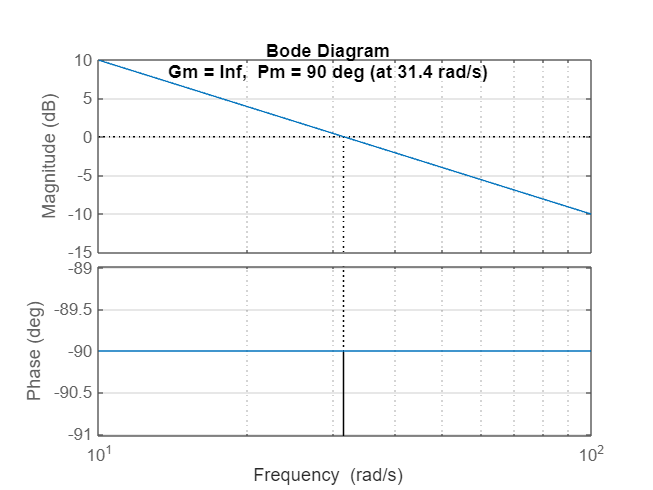

innerL = Kp * 1/Jx * 1/s; % TF from P commanded to P.
innerTF = innerL /(1 + innerL);
margin(innerL)
grid on


% Second loop.
Kphi = 10 * (2 * pi)

Kphi = 62.8319

secondL = Kphi / s; % TF from roll commanded to roll.
secondTF = secondL / (1 + secondL); % cl TF of the second loop.
margin(secondL)
grid on


% Third loop.
Kv = 2 * (2 * pi) / g

Kv = 1.2823

thirdL = Kv * g / s;
thirdTF = thirdL / (1 + thirdL);
margin(thirdL)
grid on


% Fourth loop.
Kpe = (2 / 5) * (2 * pi)

Kpe = 2.5133

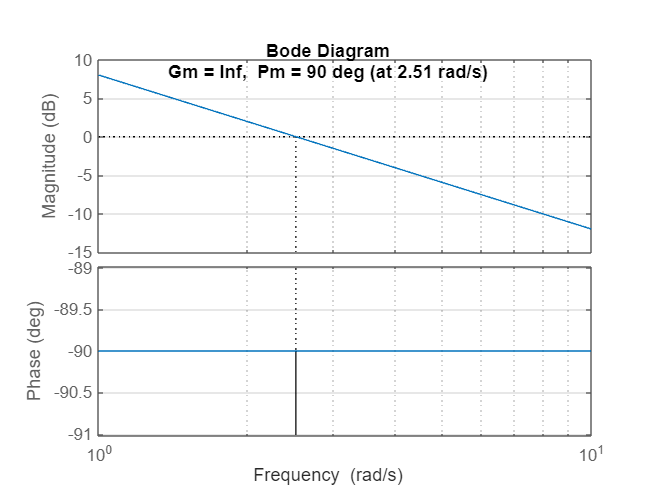

fourthL = Kpe / s;
fourthTF = fourthL / (1 + fourthL);
margin(fourthL)
grid on

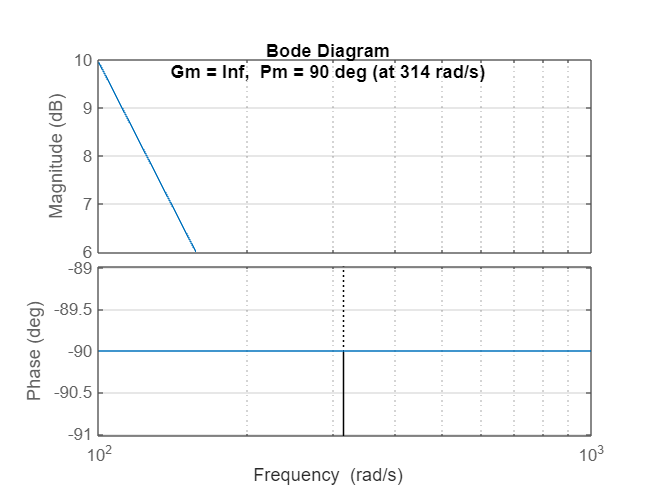






%% Control output for M.

s = tf('s');
g = 9.8; % Gravity. m/s^2.
inerMatrix = [16.57,  0.83,  0.72;
               0.83, 16.66,  1.80;
               0.72,  1.80, 29.26]; % Inertial Tensor matrix. In the body frame.

Jx = inerMatrix(1, 1);
Jxy = inerMatrix(2, 1);
Jxz = inerMatrix(3, 1);
%Jxy = inerMatrix(1, 2);
Jy = inerMatrix(2, 2);
Jyz = inerMatrix(3, 2);
%Jxz = inerMatrix(1, 3);
%Jyz = inerMatrix(2, 3);
Jz = inerMatrix(3, 3);

% Inner loop.
Pnc = 0; % Want the position to stay at 0.
Kq = 50 * (2 * pi) * Jz;
innerL = Kq / (Jz * s);
innerTF = innerL / (1 + innerL);
margin(innerL)
grid on

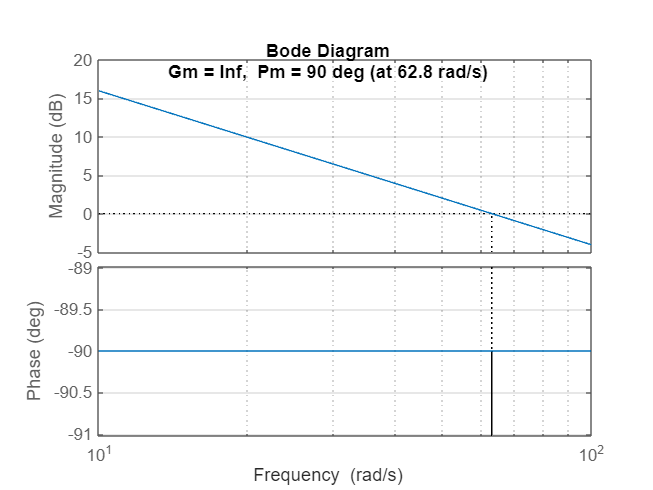


% Second loop.
Ktheta = 10 * (2 * pi);
secondL = Ktheta / s;
secondTF = secondL / (1 + secondL);
margin(secondL)
grid on

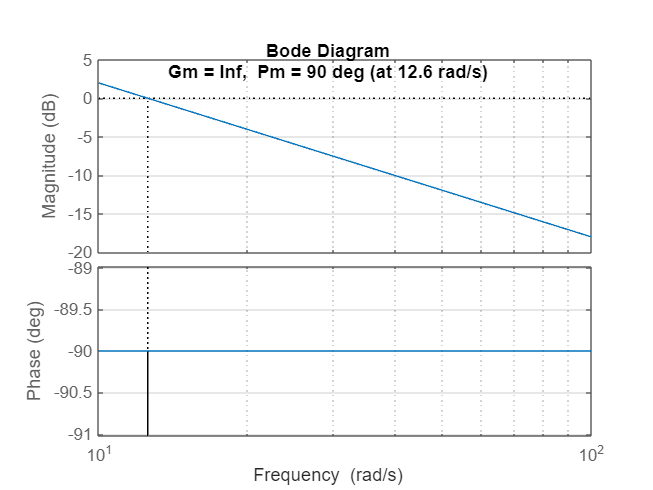


% Third loop.
Ku = 2 * (2 * pi) / g;
thirdL = Ku * g / s;
thirdTF = thirdL / (1 + thirdL);
margin(thirdL)
grid on


% Fourth loop.
Kpn = (2 / 5) * (2 * pi);
fourthL = Kpn / s;
fourthTF = fourthL / (1 + fourthL);
margin(fourthL);
grid on





%%Control output for N.
s = tf('s');
g = 9.8; % Gravity. m/s^2.
inerMatrix = [16.57,  0.83,  0.72;
               0.83, 16.66,  1.80;
               0.72,  1.80, 29.26]; % Inertial Tensor matrix. In the body frame.

Jx = inerMatrix(1, 1);
Jxy = inerMatrix(2, 1);
Jxz = inerMatrix(3, 1);
%Jxy = inerMatrix(1, 2);
Jy = inerMatrix(2, 2);
Jyz = inerMatrix(3, 2);
%Jxz = inerMatrix(1, 3);
%Jyz = inerMatrix(2, 3);
Jz = inerMatrix(3, 3);

% Inner loop.
Yawc = 0; % Don't want drone to yaw.
Kr = 50 * (2 * pi) * Jz;
innerL = Kr / (s * Jz);
innerTF = innerL / (1 + innerL);
margin(innerL)
grid on

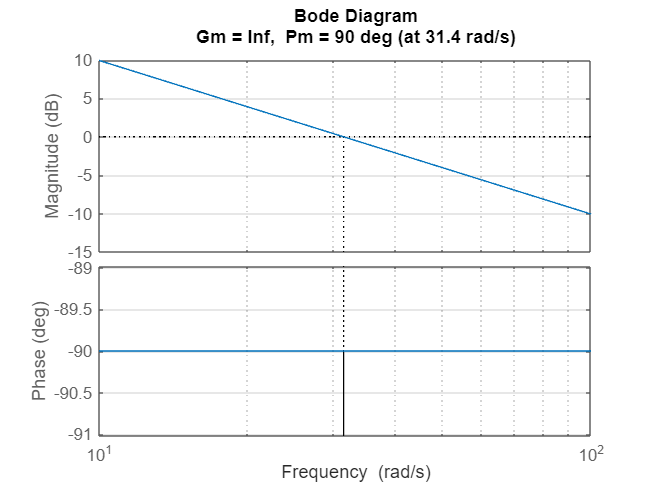


% Second loop.
Kyaw = 5 * (2 * pi);
secondL = Kyaw / s;
secondTF = secondL / (1 + secondL);
margin(secondL)
grid on



% For simulink Constants.
% Controller inputs.
fxc = 0;
fyc = 0;


%% Simulink for each individual controller output to get Gain and Phase Margins.
syms PWM Thrus torq
A = 2.13* 10 ^ -11; % From Assignment Doc.
B = 1.033 * 10 ^ -6;
C = 5.48 * 10 ^ -4;
D = 0.005964552;
E = 1.563 * 10 ^ -5;
%equaThrus =  A * PWM^2 + B * PWM + C == Thrus;

%thrusGiven = A * PWM^2 + B * PWM + C; % Given equation for thrust.
%equaTor = D * thrusGiven + E  == Torq;



% PWMFromThrust = solve(equaThrus, PWM);
% PWMFromThrust = PWMFromThrust(2)% Eqution to get PWM from thrust.


% PWMFromTor = solve(equaTor, PWM);
% PWMFromTor = PWMFromTor(2)% Equationto get PWM from Thrust.

PWMFromThrust = roots([A B (C-Thrus)]);
PWMFromThrust = PWMFromThrust(2);% Eqution to get PWM from thrust. 

PWMFromThrustFunc = @(thrust) (77371252455336267181195264 * sqrt(3296015354597325 * thrust / 38685626227668133590597632 + 182045336161068188949327330602267/178405961588244985132285746181186892047843328) / 3296015354597325 -  79924503786362355712/3296015354597325);

PWMFromTor = roots([A * D, B * D, C * D + (E - torq)]);
PWMFromTor = PWMFromTor(2);% Equationto get PWM from Thrust.
PWMFromTorFunc = @(tor)  (19807040628566084398385987584 * sqrt(5032769273675311 * tor / 9903520314283042199192993792 + 663141903269232066005393670573721 / 23384026197294446691258957323460528314494920687616) /  5032769273675311 - 122038747880436514816 / 5032769273675311);


testThrust = PWMFromThrustFunc(-3.3)

testThrust = -2.4249e+04 + 3.9290e+05i

testTor = PWMFromTorFunc(-3.3)

testTor = -2.4249e+04 + 5.0965e+06i

% PWM to Thrust TF from Slack by Dr. Bahn.
Hs = 10 / (s + 10);



%The open loop transfer function of the Z controller starting from plant
%input.

% where I left off.
% zplantTF = 1 / (mass * s * s);
% opZTF = Hs * zplantTF * Kpz * Kw * PWMFromThrust; % HOW CAN I TURN PWMFromThrust to a TF????
% margin(opZTF)
% grid on



% The mixer.

mixMat = [-0.25, -0.25, 0.25, 0.35;
          -0.25, -0.25, -0.25, -0.2;
          -0.25, 0.25, -0.25, 0.35;
          -0.25, 0.25, 0.25, -0.2];